## EXAMPLE: 2D beam, with an arc-shaped defect.

This example loosely retrace the one reported in **Section 7** (Numerical Test - I) of the paper:

Marconi, J., Tiso, P., Quadrelli, D. E., & Braghin, F. (2021). *A higher-order parametric nonlinear reduced-order model for imperfect structures using Neumann expansion*. Nonlinear Dynamics. [https://doi.org/10.1007/s11071-021-06496-y](https://doi.org/10.1007/s11071-021-06496-y) 

clear; 
close all;
clc
format short g

set analysis parameters:

FORMULATION = 'N1'; % N1/N1t/N0
VOLUME = 1;         % integration over defected (1) or nominal volume (0)

USEJULIA = 0; % use DpROM.jl (see notes in ../papers/DpROM/References.pdf)
ROMn = 1;     % compute the response for the nominal model
ROMd = 1;     % compute the response for the defected model (non-parametric ROM)

n_VMs = 3;      % use n_VMS vibration modes (and all associated MDs)
exc_lev = 4000; % excitation level

## PREPARE MODEL

% DATA ____________________________________________________________________
E       = 70e9;     % Young's modulus [Pa]
rho     = 2800;     % density [kg/m^3]
nu      = 0.30;     % Poisson's ratio 
thickness = .2;     % [m] beam's out-of-plane thickness

% Material
myMaterial = KirchoffMaterial();
set(myMaterial,'YOUNGS_MODULUS',E,'DENSITY',rho,'POISSONS_RATIO',nu);
myMaterial.PLANE_STRESS = false;	% set "true" for plane_stress
% Element
myElementConstructor = @()Quad8Element(thickness, myMaterial);

% MESH_____________________________________________________________________
Lx = 2;
Ly = .050;
h = 2;
nx = 20*h;
ny = 1*h;
[nodes, elements, nset] = mesh_2Drectangle(Lx, Ly, nx, ny, 'QUAD8');

 Meshing 80 elements (QUAD8) ...  0.00 s
  Nodes: 325 
  Dofs:  650 



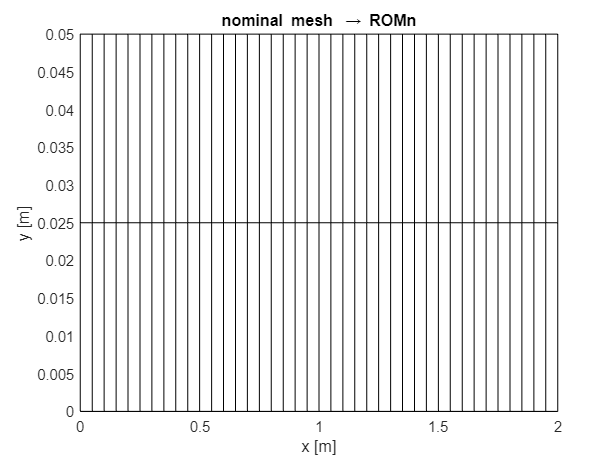

% nominal mesh
MeshNominal = Mesh(nodes);
MeshNominal.create_elements_table(elements,myElementConstructor);
MeshNominal.set_essential_boundary_condition([nset{1} nset{3}],1:2,0)

figure
PlotMesh(nodes,elements(:,1:4));
axis on normal tight; xlabel('x [m]'); ylabel('y [m]'); title('nominal mesh \rightarrow ROMn')

% defected mesh
    % arch defect
    xi = 1;                                     % defect amplitude
    yd = Ly * sin(pi/Lx * nodes(:,1));          % y-displacement 
    nodes_defected = nodes + [yd*0 yd]*xi;   	% new nodes
    arc_defect = zeros(numel(nodes),1);         
    arc_defect(2:2:end) = yd;                   % vectorized defect-field
    U = arc_defect;                             % defect basis
MeshDefected = Mesh(nodes_defected);
MeshDefected.create_elements_table(elements,myElementConstructor);
MeshDefected.set_essential_boundary_condition([nset{1} nset{3}],1:2,0)
fprintf(' Arc defect: %.1f * beam thickness \n\n', xi)

 Arc defect: 1.0 * beam thickness 



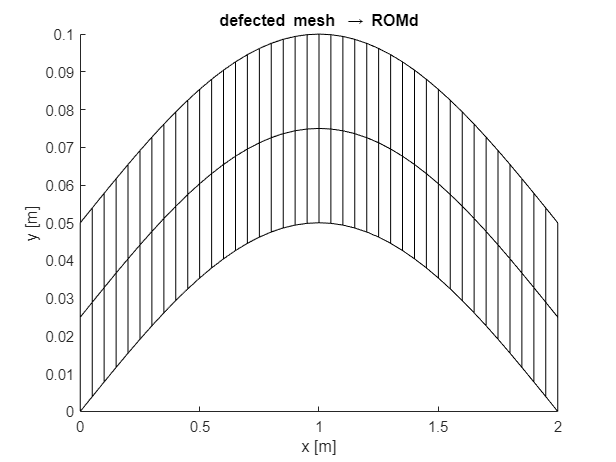

figure
PlotMesh(nodes_defected,elements(:,1:4));
axis on normal tight; xlabel('x [m]'); ylabel('y [m]'); title('defected mesh \rightarrow ROMd')

% ASSEMBLY ________________________________________________________________
% nominal
NominalAssembly = Assembly(MeshNominal);
Mn = NominalAssembly.mass_matrix();
nNodes = size(nodes,1);
u0 = zeros( MeshNominal.nDOFs, 1);
[Kn,~] = NominalAssembly.tangent_stiffness_and_force(u0);
    % store matrices
    NominalAssembly.DATA.K = Kn;
    NominalAssembly.DATA.M = Mn;

% defected
DefectedAssembly = Assembly(MeshDefected);
Md = DefectedAssembly.mass_matrix();
[Kd,~] = DefectedAssembly.tangent_stiffness_and_force(u0);
    % store matrices
    DefectedAssembly.DATA.K = Kd;
    DefectedAssembly.DATA.M = Md;

% External force __________________________________________________________
node_dofs = MeshNominal.get_DOF_from_location([Lx/2, Ly/2]);
forced_dof = node_dofs(2);
Fext = zeros(nNodes*2, 1);
Fext( forced_dof ) = 1;
Fextc = NominalAssembly.constrain_vector( Fext );

% Let us also define the index of the forced dof in the constrained vector:
forced_dof_c = NominalAssembly.free2constrained_index( forced_dof );

## Eigenmodes

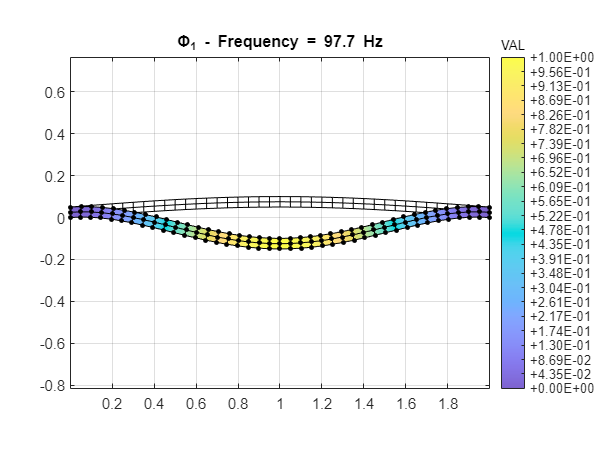

% Eigenvalue problem_______________________________________________________
% Vibration Modes (VM): nominal
Knc = DefectedAssembly.constrain_matrix(Kn);
Mnc = DefectedAssembly.constrain_matrix(Mn);
[VMn,om] = eigs(Knc, Mnc, n_VMs, 'SM');
[f0n,ind] = sort(sqrt(diag(om))/2/pi);
VMn = VMn(:,ind);
for ii = 1:n_VMs
    VMn(:,ii) = VMn(:,ii)/max(sqrt(sum(VMn(:,ii).^2,2)));
end
VMn = NominalAssembly.unconstrain_vector(VMn);

% Vibration Modes (VM): defected
Kdc = DefectedAssembly.constrain_matrix(Kd);
Mdc = DefectedAssembly.constrain_matrix(Md);
[VMd,om] = eigs(Kdc, Mdc, n_VMs, 'SM');
[f0d,ind] = sort(sqrt(diag(om))/2/pi);
VMd = VMd(:,ind);
for ii = 1:n_VMs
    VMd(:,ii) = VMd(:,ii)/max(sqrt(sum(VMd(:,ii).^2,2)));
end
VMd = NominalAssembly.unconstrain_vector(VMd);

% PLOT (defected)
mod = 1;
figure
PlotMesh(nodes_defected, elements(:,1:4), 0);
v1 = reshape(VMd(:,mod), 2, []).';
S = 2*max(nodes_defected(:,2));
PlotFieldonDeformedMesh(nodes_defected, elements(:,1:4), v1, 'factor', S);
title(['\Phi_' num2str(mod) ' - Frequency = ' num2str(f0d(mod),3) ' Hz'])
axis on; grid on; box on

% Damping _________________________________________________________________
alfa = 3.1;
beta = 6.3*1e-6;
D = alfa*Mn + beta*Kn;
NominalAssembly.DATA.D = D;
Dc = NominalAssembly.constrain_matrix(D);

## Modal Derivatives & Defect Sensitivities

compute the vectors to include in the reduction bases

[MDn, MDnames] = modal_derivatives(NominalAssembly,  elements, VMn, USEJULIA); % nominal

 dKdq, assembling 80 elements ... 0.18 s
 dKdq, assembling 80 elements ... 0.17 s
 dKdq, assembling 80 elements ... 0.18 s


MDd            = modal_derivatives(DefectedAssembly, elements, VMd, USEJULIA); % defected

 dKdq, assembling 80 elements ... 0.17 s
 dKdq, assembling 80 elements ... 0.16 s
 dKdq, assembling 80 elements ... 0.16 s



[DS, names] = defect_sensitivities(NominalAssembly, elements, VMn, U, ...
    FORMULATION, USEJULIA); % for DpROM

 dKdxi, assembling 80 elements ... 0.03 s
 


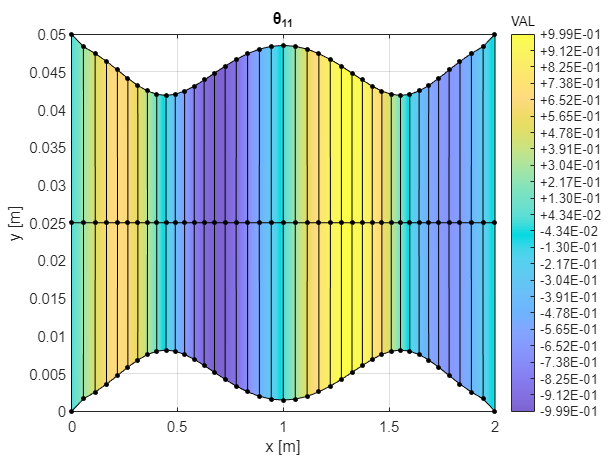

% PLOT a MD (color = axial displacement)
nwho = 1;
elementPlot = elements(:,1:4); % plot only corners (otherwise it's a mess)
figure
v1 = reshape(MDn(:, nwho), 2, []).';
S = Ly/2;
PlotFieldonDeformedMesh(nodes, elementPlot, v1, 'factor', S, 'component', 'U1');
title(['\theta_{' num2str(MDnames(nwho,1)) num2str(MDnames(nwho,2)) '}'])
axis on normal tight; xlabel('x [m]'); ylabel('y [m]'); grid on; box on

## (Dp)ROM

construct the stiffness tensors for the nominal, defected and parametric ROM

V  = [VMn MDn DS]; 	% reduced order basis (DpROM)
Vn = [VMn MDn];   	% reduced order basis (ROM-n)
Vd = [VMd MDd];   	% reduced order basis (ROM-d)

V  = orth(V);
Vn = orth(Vn);
Vd = orth(Vd);

if ROMn==1
    tensors_ROMn = reduced_tensors_ROM(NominalAssembly, elements, ...
        Vn, USEJULIA);
end

 REDUCED TENSORS (standard ~ using Matlab):
 Assembling 80 elements ... 2.18 s (2.18 s)
 SPEED: 36.8 el/s
 SIZEs: 9 



if ROMd==1
    tensors_ROMd = reduced_tensors_ROM(DefectedAssembly, elements, ...
        Vd, USEJULIA);
end

 REDUCED TENSORS (standard ~ using Matlab):
 Assembling 80 elements ... 2.17 s (2.17 s)
 SPEED: 36.9 el/s
 SIZEs: 9 



tensors_DpROM = reduced_tensors_DpROM(NominalAssembly, elements, V, ...
        U, FORMULATION, VOLUME, USEJULIA);

 REDUCED TENSORS (N1 ~ using Matlab):
 Assembling 80 elements ... 1.46 s (1.46 s)
 SPEED: 54.7 el/s
 SIZEs: 12 - 1 




% evaluate the defected tensors at xi [Eqs. (28)]
[Q2, Q3, Q4, Q3t, Q4t] = DefectedTensors(tensors_DpROM, xi);

% check eigenfrequencies
if ROMd == 1
    Mnr = V'*Mn*V;      % reduced mass matrix (DpROM)
    Mdr = Vd'*Md*Vd; 	% reduced mass matrix (ROM-d)
    f0_ROMd = sort(sqrt(eig(Mdr\tensors_ROMd.Q2))/2/pi);
    f0_DpROM = sort(sqrt(eig(Mnr\Q2))/2/pi);
    id = 1 : n_VMs;
    f0_ROMd = f0_ROMd(id);
    f0_DpROM = f0_DpROM(id);
    disp(table(f0n, f0d, f0_ROMd, f0_DpROM))
end

     f0n       f0d      f0_ROMd    f0_DpROM
    ______    ______    _______    ________
    67.223    97.709    97.709      97.871 
    184.23    183.11    183.11      183.12 
    358.41    356.81    356.81      356.83 


## ROMn: FRF - Harmonic Balance (with NLvib)

if ROMn == 1

% PREPARE MODEL ___________________________________________________________
% ROMn: reduced matrices
Kr = tensors_ROMn.Q2;    % reduced linear stiffness matrix
Mr = Vn' * Mn * Vn;     % reduced mass matrix
Dr = Vn' * D  * Vn;     % reduced damping matrix
Fr = Vn'*Fext;          % reduced external force vector

% Let us defined the ROMn Assembly (although the ReducedAssembly class is
% not strictly necessary, we want to define a different object - remember
% that the synthax obj1=obj2 does NOT copy an object)
ROMn_Assembly = Assembly(MeshNominal, Vn); 
ROMn_Assembly.DATA.K = Kr;
ROMn_Assembly.DATA.M = Mr;
ROMn_Assembly.DATA.D = Dr;
ROMn_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(...
    tensors_ROMn.Q3,tensors_ROMn.Q4, tensors_ROMn.Q3t, tensors_ROMn.Q4t,q);
ROMn_System = FE_system(ROMn_Assembly, Fr, 'custom');

% ANALYSIS PARAMETERS _____________________________________________________
imod = 1;               % eigenfreq to study
omi = 2*pi*f0n(imod); 	% linear eigenfrequency
n = size(Vn, 2);        % number of DOFs of the reduced system
H = 3;                  % harmonic order
N = 3*H+1;              % number of time samples per period
Om_s = omi * 0.80;   	% start frequency
Om_e = omi * 1.5;    	% end frequency
ds = 10;                % Path continuation step size

% COMPUTE FRs _____________________________________________________________
fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)
r1 = cell(length(exc_lev),1);
for iex = 1 : length(exc_lev)
    % Set excitation level
    ROMn_System.Fex1 = Vn' * Fext * exc_lev(iex);
    
    % Initial guess (solution of underlying linear system)
    Q1 = (-Om_s^2*Mr + 1i*Om_s*Dr + Kr) \ ROMn_System.Fex1;
    y0 = zeros( (2*H+1)*n , 1);
    y0( n + (1:2*n) ) = [real(Q1);-imag(Q1)];
    
    % stuff for scaling
    qscl = max(abs((-omi^2*Mr + 1i*omi*Dr + Kr) \ ROMn_System.Fex1));
    dscale = [y0*0+qscl; omi];
    Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1,...
        'dsmax',ds*2, 'stepmax', 1e4);
    
    % Solve and continue w.r.t. Om	
    [X, Solinfo, Sol] = solve_and_continue(y0, ...
        @(X) HB_residual(X, ROMn_System, H, N, 'FRF'), ...
        Om_s, Om_e, ds, Sopt);
    
    % Interpret solver output
    r1{iex} = nlvib_decode(X, Solinfo, Sol, 'FRF', 'HB', n, H);
end
end



 FRF from 337.90 to 633.56 rad/s 



NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     4.02802e+08                       1.1e+14               1
     1          2        0.434331     0.00013131        3.7e+09               1
     2          3     2.71822e-08    2.54477e-06       9.25e+05               1
     3          4     5.16215e-23    4.88988e-12         0.0462               1
     4          5     2.34743e-23    4.39546e-18         0.0224               1



## ROMd: FRF - Harmonic Balance (with NLvib)

if ROMd == 1

% PREPARE MODEL ___________________________________________________________
% ROMd: reduced matrices
Kr = tensors_ROMd.Q2;    % reduced linear stiffness matrix
Mr = Vd' * Md * Vd;     % reduced mass matrix
Dr = Vd' * D  * Vd;     % reduced damping matrix
Fr = Vd'*Fext;          % reduced external force vector

% Let us defined the ROMd Assembly (although the ReducedAssembly class is
% not strictly necessary, we want to define a different object - remember
% that the synthax obj1=obj2 does NOT copy an object)
ROMd_Assembly = Assembly(MeshDefected, Vd); 
ROMd_Assembly.DATA.K = Kr;
ROMd_Assembly.DATA.M = Mr;
ROMd_Assembly.DATA.D = Dr;
ROMd_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(...
    tensors_ROMd.Q3,tensors_ROMd.Q4, tensors_ROMd.Q3t, tensors_ROMd.Q4t,q);
ROMd_System = FE_system(ROMd_Assembly, Fr, 'custom');

% ANALYSIS PARAMETERS _____________________________________________________
imod = 1;               % eigenfreq to study
omi = 2*pi*f0d(imod); 	% linear eigenfrequency
n = size(Vd, 2);        % number of DOFs of the reduced system
H = 3;                  % harmonic order
N = 3*H+1;              % number of time samples per period
Om_s = omi * 1.20;   	% start frequency
Om_e = omi * 0.8;    	% end frequency
ds = 20;                % Path continuation step size

% COMPUTE FRs _____________________________________________________________
fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)
r2 = cell(length(exc_lev),1);
for iex = 1 : length(exc_lev)
    % Set excitation level
    ROMd_System.Fex1 = Vd' * Fext * exc_lev(iex);
    
    % Initial guess (solution of underlying linear system)
    Q1 = (-Om_s^2*Mr + 1i*Om_s*Dr + Kr) \ ROMd_System.Fex1;
    y0 = zeros( (2*H+1)*n , 1);
    y0( n + (1:2*n) ) = [real(Q1);-imag(Q1)];
    
    % stuff for scaling
    qscl = max(abs((-omi^2*Mr + 1i*omi*Dr + Kr) \ ROMd_System.Fex1));
    dscale = [y0*0+qscl; omi];
    Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1,...
        'dsmax',ds*2, 'stepmax', 1e4);
    
    % Solve and continue w.r.t. Om	
    [X, Solinfo, Sol] = solve_and_continue(y0, ...
        @(X) HB_residual(X, ROMd_System, H, N, 'FRF'), ...
        Om_s, Om_e, ds, Sopt);
    
    % Interpret solver output
    r2{iex} = nlvib_decode(X, Solinfo, Sol, 'FRF', 'HB', n, H);
end
end



 FRF from 736.71 to 491.14 rad/s 



NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     3.05864e+06                      2.13e+12               1
     1          2       0.0762774    0.000187221       4.56e+08               1
     2          3     5.09248e-15    9.32801e-08            122               1
     3          4     1.27544e-21    1.88519e-14         0.0707               1

Equation solved, solver stalled.

fsolve stopped 

## DpROM: FRF - Harmonic Balance (with NLvib)

% PREPARE MODEL ___________________________________________________________
% ROMd: reduced matrices
Kr = Q2;         	% reduced linear stiffness matrix
Mr = V' * Md * V;  	% reduced mass matrix
Dr = V' * D  * V; 	% reduced damping matrix
Fr = V'*Fext;    	% reduced external force vector

% Let us defined the ROMd Assembly (although the ReducedAssembly class is
% not strictly necessary, we want to define a different object - remember
% that the synthax obj1=obj2 does NOT copy an object)
DpROM_Assembly = Assembly(MeshNominal, V); 
DpROM_Assembly.DATA.K = Kr;
DpROM_Assembly.DATA.M = Mr;
DpROM_Assembly.DATA.D = Dr;
DpROM_Assembly.DATA.fnl_CUSTOM = @(q, qd, qdd) tensors_KF_NLvib(Q3,...
    Q4, Q3t, Q4t, q);
DpROM_System = FE_system(DpROM_Assembly, Fr, 'custom');

% ANALYSIS PARAMETERS _____________________________________________________
imod = 1;               % eigenfreq to study
omi = 2*pi*f0d(imod); 	% linear eigenfrequency
n = size(V, 2);         % number of DOFs of the reduced system
H = 3;                  % harmonic order
N = 3*H+1;              % number of time samples per period
Om_s = omi * 1.20;   	% start frequency
Om_e = omi * 0.8;    	% end frequency
ds = 20;                % Path continuation step size

% COMPUTE FRs _____________________________________________________________
fprintf('\n\n FRF from %.2f to %.2f rad/s \n\n', Om_s, Om_e)



 FRF from 736.71 to 491.14 rad/s 



r3 = cell(length(exc_lev),1);
for iex = 1 : length(exc_lev)
    % Set excitation level
    DpROM_System.Fex1 = V' * Fext * exc_lev(iex);
    
    % Initial guess (solution of underlying linear system)
    Q1 = (-Om_s^2*Mr + 1i*Om_s*Dr + Kr) \ DpROM_System.Fex1;
    y0 = zeros( (2*H+1)*n , 1);
    y0( n + (1:2*n) ) = [real(Q1);-imag(Q1)];
    
    % stuff for scaling
    qscl = max(abs((-omi^2*Mr + 1i*omi*Dr + Kr) \ DpROM_System.Fex1));
    dscale = [y0*0+qscl; omi];
    Sopt = struct('Dscale', dscale, 'dynamicDscale', 1, 'dsmin',ds/1e3,...
        'dsmax',ds*2, 'stepmax', 1e4);
    
    % Solve and continue w.r.t. Om	
    [X, Solinfo, Sol] = solve_and_continue(y0, ...
        @(X) HB_residual(X, DpROM_System, H, N, 'FRF'), ...
        Om_s, Om_e, ds, Sopt);
    
    % Interpret solver output
    r3{iex} = nlvib_decode(X, Solinfo, Sol, 'FRF', 'HB', n, H);
end

NLvib Version 1.3, Copyright (C) 2020 Malte Krack, Johann Gross
This program comes with ABSOLUTELY NO WARRANTY.
This is free software, and you are welcome to redistribute
it under certain conditions, see gpl-3.0.txt.
Find initial solution.
--------------------

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          1     2.33998e+07                      2.84e+13               1
     1          2        0.588465    0.000204617       5.92e+09               1
     2          3     4.02378e-14    1.01713e-07       1.53e+03               1
     3          4     2.74369e-21     2.0631e-14          0.403               1

Equation solved, solver stalled.

fsolve stopped 

## PLOT FRs

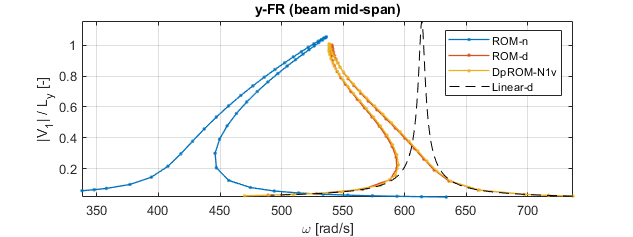

h = 1; % plot h-th harmonic

figure('units','normalized','position',[.2 .3 .6 .4])
if ROMn == 1
    for iex = 1 : length(exc_lev)
        % 1st harmonic amplitude of the forced dof (use force_dof_c!)
        A = r1{iex}.Qre(:, :, h);
        B = r1{iex}.Qim(:, :, h);

        c = Vn * (A + 1i*B);  % project back reduced solution to full space
        cu = c(forced_dof-1, :);
        cv = c(forced_dof,   :);

        W = r1{iex}.omega;
        
        plot(W, abs(cv) / Ly, '.-', 'linewidth', 1, 'DisplayName','ROM-n');
        hold on
    end
end

if ROMd == 1
    for iex = 1 : length(exc_lev)
        % 1st harmonic amplitude of the forced dof (use force_dof_c!)
        A = r2{iex}.Qre(:, :, h);
        B = r2{iex}.Qim(:, :, h);

        c = Vd * (A + 1i*B);  % project back reduced solution to full space
        cu = c(forced_dof-1, :);
        cv = c(forced_dof,   :);

        W = r2{iex}.omega;
        
        plot(W, abs(cv) / Ly, '.-', 'linewidth', 1, 'DisplayName','ROM-d');
        hold on
    end
end

for iex = 1 : length(exc_lev)
    % 1st harmonic amplitude of the forced dof (use force_dof_c!)
    A = r3{iex}.Qre(:, :, h);
    B = r3{iex}.Qim(:, :, h);

    c = V * (A + 1i*B);  % project back reduced solution to full space
    cu = c(forced_dof-1, :);
    cv = c(forced_dof,   :);

    W = r3{iex}.omega;
    v = [];
    if tensors_DpROM.volume == 1
        v = 'v';
    end
    
    plot(W, abs(cv) / Ly, '.-', 'linewidth', 1, 'DisplayName',...
        ['DpROM-' tensors_DpROM.formulation v]); 
    hold on
    grid on
    axis tight
    xlabel('\omega [rad/s]')
    ylabel('|V_1| / L_y [-]')
    title('y-FR (beam mid-span)')
end

% LINEAR RESPONSE
% compute the linear FRF for comparison
nw = 501;
w_linear = linspace(Om_s, Om_e, nw);
for iex = 1 : length(exc_lev)
    fr_linear = zeros(nNodes*2, nw);
    for ii = 1:nw
        w = w_linear(ii);
        frl = (VMd'*(-w^2*Md + 1i*w*D + Kd)*VMd) \ (VMd'*Fext) * exc_lev(iex);
        fr_linear(:, ii) = VMd * frl;
    end
    plot(w_linear, abs(fr_linear(forced_dof, :))/Ly, 'k--', ...
        'DisplayName','Linear-d')
end
legend